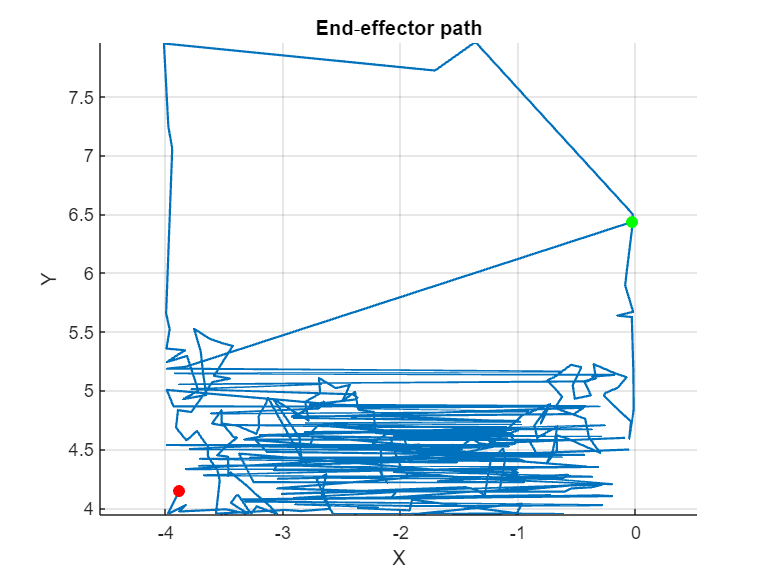

%{
@file verify_thetas.m
@brief Plot the end‑effector path reconstructed from joint angles stored in *new_thetas.txt*.
@details
This standalone script performs three key steps:
1. **Load** planar joint angles `θ₁`, `θ₂` (degrees) recorded by *image_to_thetas.py*.
2. **Forward‑kinematics**: convert to radians, apply the mechanical zero offset on `θ₂`,
   and compute the planar (x,y) tool position of a two‑link RR manipulator.
3. **Visualize** the resulting Cartesian trajectory, marking the start (green) and end (red).

@note The link lengths (`L1`, `L2`) and the `offsetT2` constant **must** match those used
      by *image_to_thetas.py* when the data were produced. Otherwise the plot will be
      geometrically inconsistent.

@author Dylan Featherson
@date 2025‑06‑12
%}

%% Robot geometry constants ------------------------------------------------
% @var L1  Link‑1 length (units: inch or cm — be consistent)
% @var L2  Link‑2 length (same units as *L1*)
% @var offsetT2  Angle [deg] such that θ₂ = 0° when link‑2 is +offsetT2° from +X
L1 = 5.816;          % link‑1 length
L2 = 5.928;          % link‑2 length
offsetT2 = 148;      % θ₂ = 0° when link‑2 is +148° from +X

%% Load joint‑angle log ----------------------------------------------------
% @section io
% Opens *new_thetas.txt* and reads the first two joint angles.  Each line is
% formatted as `{θ1, θ2, θ3},…` — the third value is ignored because the
% prismatic pen axis is handled separately.
fid = fopen('new_thetas.txt','r');
if fid == -1
    error('Cannot open new_thetas.txt');
end

C = textscan(fid,'{%f, %f, %*f},%*[^\n]');
fclose(fid);

theta1 = C{1};   % [deg] Joint‑1 (base) rotation; negative values ⇒ CW
theta2 = C{2};   % [deg] Joint‑2 (elbow) rotation

%% Forward kinematics -------------------------------------------------------
% @section kinematics
% Convert degrees → radians, undo mechanical offset on θ₂, then compute the
% planar forward kinematics of a two‑link RR arm.
th1 = deg2rad(-theta1);                % sign convention: CW negative
th2 = deg2rad(theta2) + deg2rad(offsetT2);  % reference adjustment

x = L1*cos(th1) + L2*cos(th1 + th2);   % [units] Cartesian X of tool‑tip
y = L1*sin(th1) + L2*sin(th1 + th2);   % [units] Cartesian Y of tool‑tip

%% Plot end‑effector path ---------------------------------------------------
% @section plotting
% Generates a 2‑D plot of the reconstructed tool path.
figure('Name','Re‑created tool‑path from new_thetas.txt');
hold on; axis equal
plot(x, y, '-', 'LineWidth', 1.2);                 % trajectory
plot(x(1), y(1), 'go', 'MarkerFaceColor','g');     % start marker
plot(x(end), y(end), 'ro', 'MarkerFaceColor','r'); % end marker
xlabel('X'); ylabel('Y');
title('End‑effector path');
grid on